**Below we recover the mean-field dynamics of particles interacting under logarithmic attraction, related to the Keller-Segel model for chemotaxis. For **$\omega=1$**, we recover the full system, whereas for **$\omega=20$** we recover the homogenized system. **

## Load particle data

addpath(genpath('../'))
set(0,'DefaultFigurePosition',[1200 800 580 406])
clear all
close all
clc

select_example = 1;
examples = {'extrinsic_noise','constant_intrinsic_noise'};

if isequal(examples{select_example},'extrinsic_noise')
    load('datasets/log2D_N4000_nu0.mat'); 
    extrinsic_nz=10^(-1);
elseif isequal(examples{select_example},'constant_intrinsic_noise')
    load('datasets/log2D_N4000.mat'); extrinsic_nz = 0;
end

## Compute approximate particle distribution (Xscell, t)

%%% choose experiments from Xscell to use in regression 
exps = 1:8;

%%% choose number of particles to use from each experiment
NN = size(Xscell{1},1);

%%% choose histogram grid resolution
numx = 128 + 1;
numsdv = 3;
custdom = [];
coarsen_data = [[0 1 1];[0 1 1];[0 1 1]];
scoord = 0;

%%% set extrinsic noise level
Xsnz = [extrinsic_nz 1];

%%% compute histogram
get_particle_distrib;

exps num does not exist,using available exps
ET_load_data = 0.1978 


plotgap=1;
plot_distrib;

## Choose model library

%%% local autonomous operators
max_dx = 0;
max_dt = 0;
polys = [];
trigs = [];
use_all_dt = 0;
use_cross_dx = 0;
custom_add = [];
custom_remove = {@(mat,lhs) find(all([mat(:,2)==0 mat(:,3)==0 ~ismember(mat,lhs,'rows')],2))};
toggle_comb = 1;

%%% local non-autonomous operators
driftpolys=[0:5]; drifttrigs=[];
diffpolys=[]; difftrigs=[0:2]; crossdrift=1;

%%% non-local operators
dim = size(Xscell{1},2)+1;
convargs = {{'dimx',dim-1,'utagin',1,'utagout',1,'psitags',1,'Mon',[1:5],'Sing',[-1:0.5:0],'Exp',[],'Singeps',[0.01],'svdtol',[1e-4]}};

set_library;

ET_build_lib = 1.2633 


## Set discretization

phi_class = {1,1};
sm_x = 3;
sm_t = 5;

%%% manually set test function params
p_x = 5; mxs = 25;
tau_x = []; k_x = []; tauhat_x = []; 
p_t = 3; mts = 8;
tau_t = []; k_t = []; tauhat_t = [];

% %%% set test fcn params using cornerpoint
% tauhat_x = 0.5; tau_x = 10^-6;
% p_x = []; mxs = 1;
% tauhat_t = 0.3; tau_t = 10^-3;
% p_t = []; mts = 1;

%%% rescale coordinates and/or use approx. variance for improved conditioning
scales = 2;
covtol = 0;

%%% trim rows with low particle density
trim_tags = [1 zeros(1,dim-1) 0]; 
trim_fcn = {@(col) max(col/max(abs(col)),eps)};
inds_keep_fcn = @(col) log10(col)>-2;

set_discretization;

ET_setdisc = 1.1867 


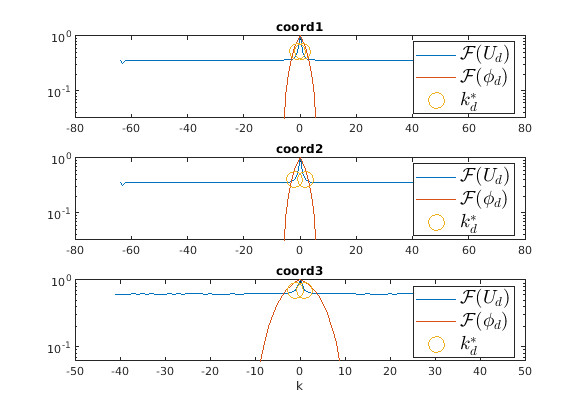


toggle_plot_fft = 1;
plot_Ufft;

## Build linear systems

build_Gb;

ET_build_Gb = 5.4802 


## Solve linear system

lambda = 10.^(linspace(-4, 0, 100));
gamma_tol = Inf;
alpha = 0.5;
maxits = Inf;
sparsity_scale = 0;
excl_tags={'u^{1}_{lap}','u^{1}_{xx}','([x.^0.*t.^0]u^1)_{xx}','([x.^0.*y.^0.*t.^0]u^1)_{lap}'};
excl_tols=0;
tol = 10^-8; 
maxQPits = 100; 
dispQP = 'off';
meth = 'STLSQP';

sparsereg_script;

ET_solve_sparse_reg = 2.1495 


## get_results

print_loc = 1;
get_results;


Recovered PDE: u^{1}_{t} = 0.157511convsing-1
Relative Res: ||b-G*W||_2/||b||_2 = 1.82e-01
Max Weight Error: max|W-W_{true}| = 1.03e-02
TP Score = 1.00
      
polys = 1 
trigs =  
Max derivs [t x] = 1 2 
[m_x m_t] = 25 8 
[s_x s_t] = 8 1 
[p_x p_t] = 5 3 
 scales = 1.00e+00 4.06e+00 4.06e+00 1.25e+00 
      
Total particles = 4000 
Size of dataset = 128 128 81 
Size G = 6500 68 
Cond G = 7.76e+06
[lambda_hat gamma] = 2.009e-02 0.000e+00 
[sigma_NR sigma] = 0.000e+00 
      
STLS its = 3 
 
ET_load_data = 0.1978 
ET_build_lib = 1.2633 
ET_setdisc = 1.1867 
ET_build_Gb = 5.4802 
ET_solve_sparse_reg = 2.1495 
Elapsed time WSINDy = 10.2774 


## Display loss

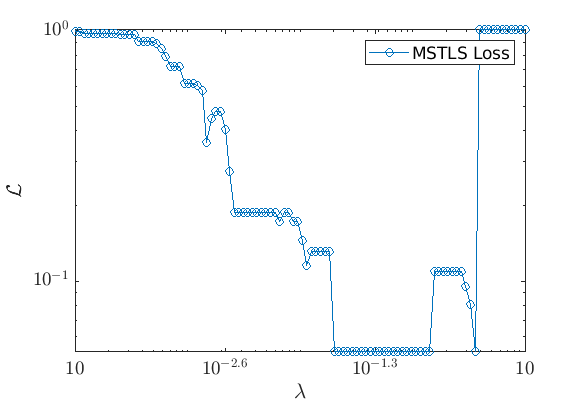

toggle_plot_loss = 1;
plot_loss;

## Display drift/diffusion

toggle_plot_drift = 0;
plot_driftdiff;

## Display interaction force

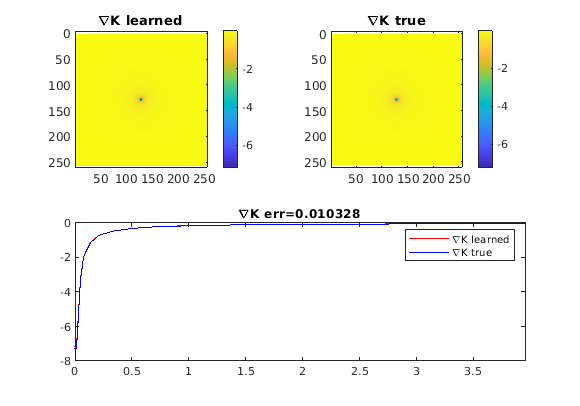

toggle_plot_IPforce = 1;
plot_K